load('TTC data files/B1965run2.mat')

Inflation pressure of 12 psi goes from 1-19984

12 psi, 0 camber is 1-7495

1-1249

1250-2498

2499-3746

3747-4996

4997-6245

6246-7495

Group data:

length=size(ET);
scalefactor=0.6;
[loadlb,loadub]=groupdata(FZ(1:7495),6,100,0);

loadlb =            1
        1250
        2499
        3747
        4997
        6246


loadub =         1249
        2498
        3746
        4996
        6245
        7495


Fit Pacejka function to data:

%for i=1:size(loadlb,1)
%    start = 0;
%    if (i>1)
%        start=loadub(i-1);
%    end
%    [SAlb,SAub]=groupdata(SA(loadlb(i):loadub(i)),3,0.19,start);
%    fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA
%    fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));
%end
C=zeros(12,4);
[SAlb,SAub]=groupdata(SA(loadlb(1):loadub(1)),3,0.19,0);
C(1,:) = fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA

ans =     12     4



Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.000000e+02.



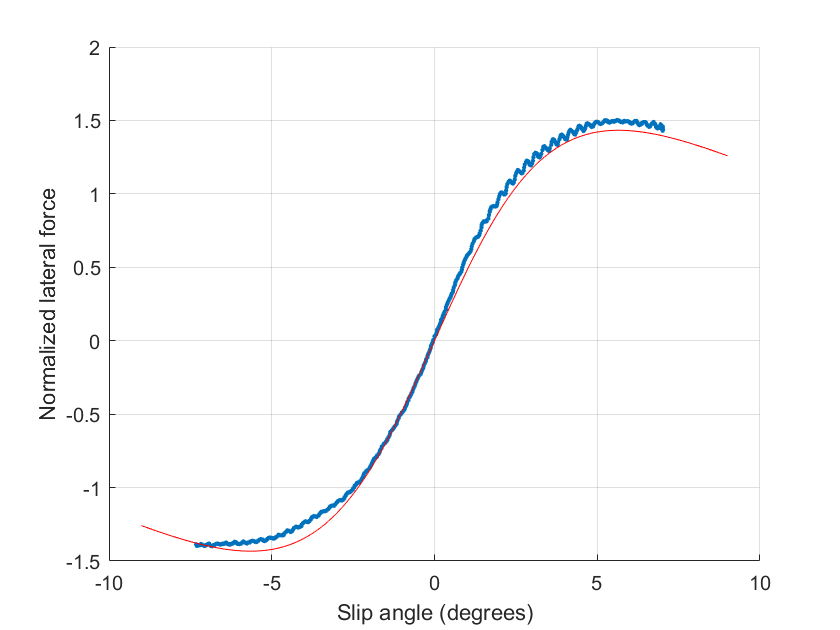


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.000000e+02.



C(2,:) = fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));


[SAlb,SAub]=groupdata(SA(loadlb(2):loadub(2)),3,0.19,loadub(1))

SAlb =         1250
        1559
        2187


SAub =         1558
        2186
        2498


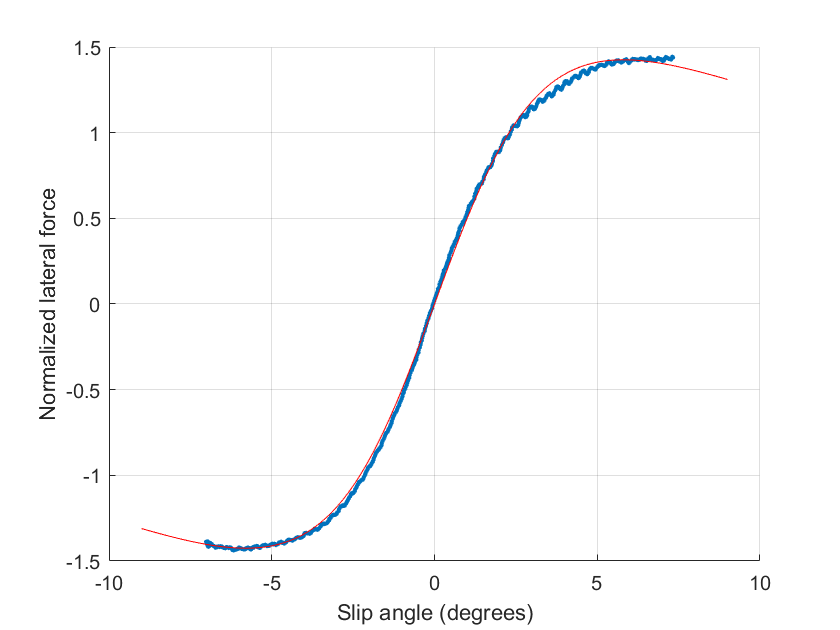


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.000000e+02.



C(3,:) = fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA

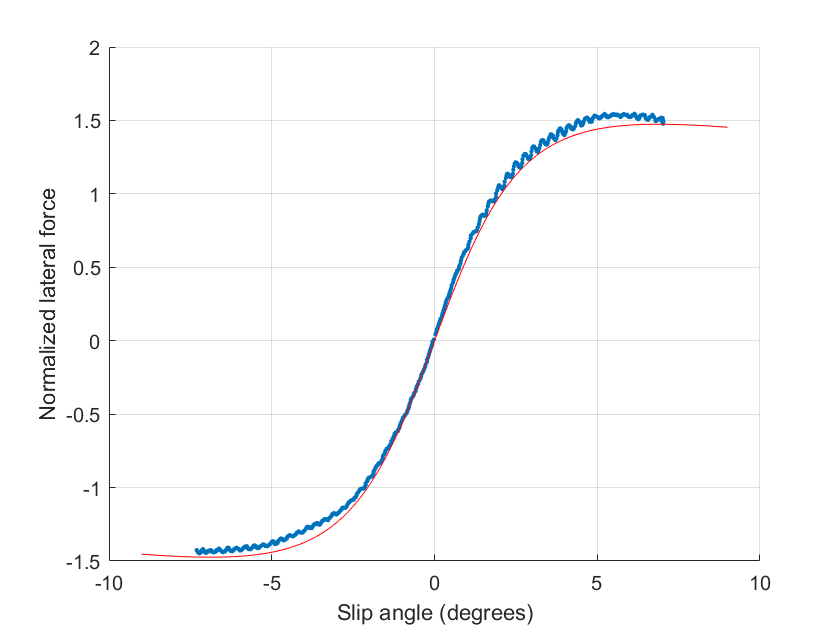


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.000000e+02.



C(4,:) = fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));


[SAlb,SAub]=groupdata(SA(loadlb(3):loadub(3)),3,0.19,loadub(2))

SAlb =         2499
        2809
        3436


SAub =         2808
        3435
        3746


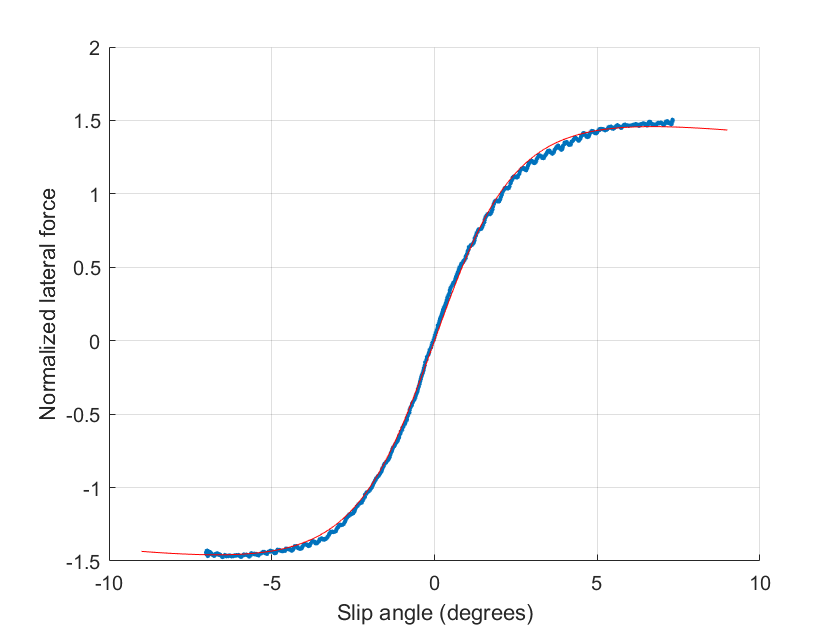


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.000000e+02.



C(5,:) = fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA

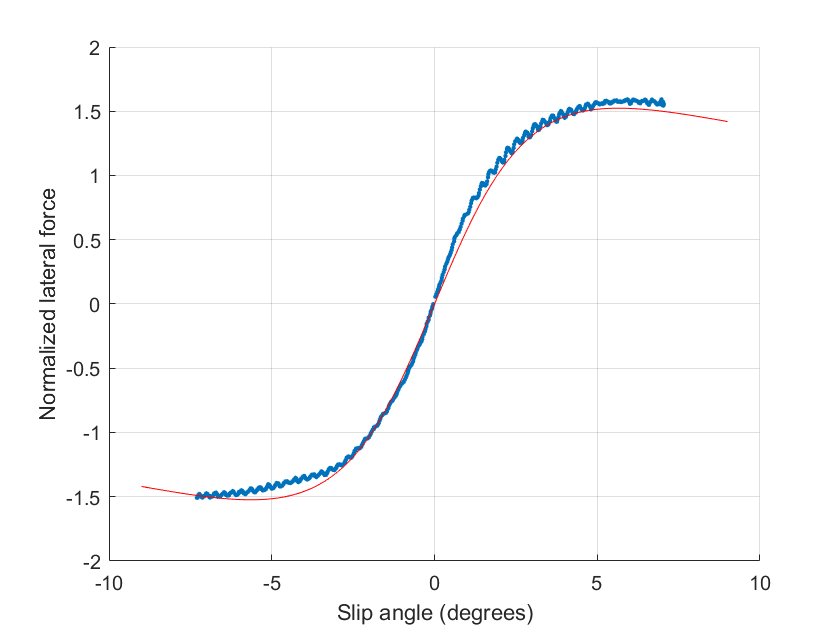


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


C(6,:) = fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));


[SAlb,SAub]=groupdata(SA(loadlb(4):loadub(4)),3,0.19,loadub(3))

SAlb =         3747
        4063
        4686


SAub =         4062
        4685
        4996


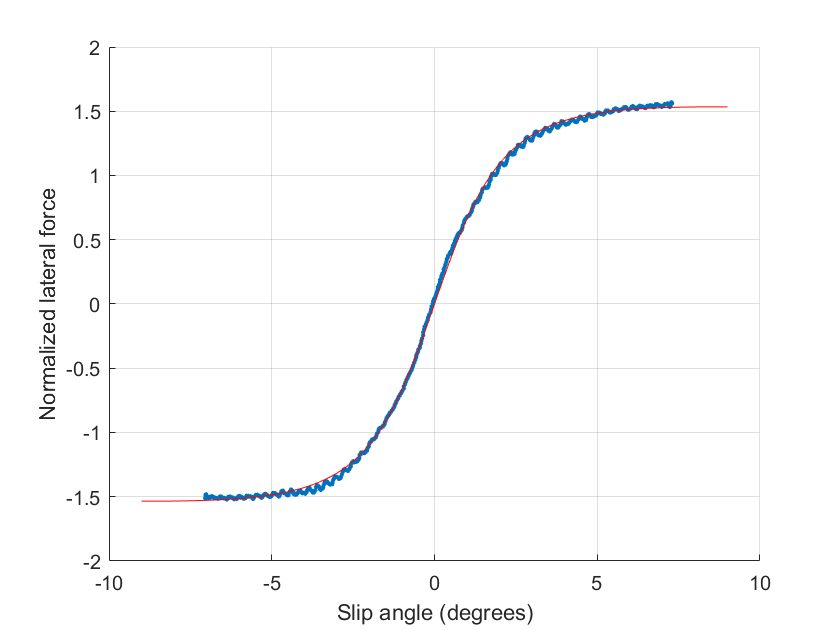


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.000000e+02.



C(7,:) = fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA

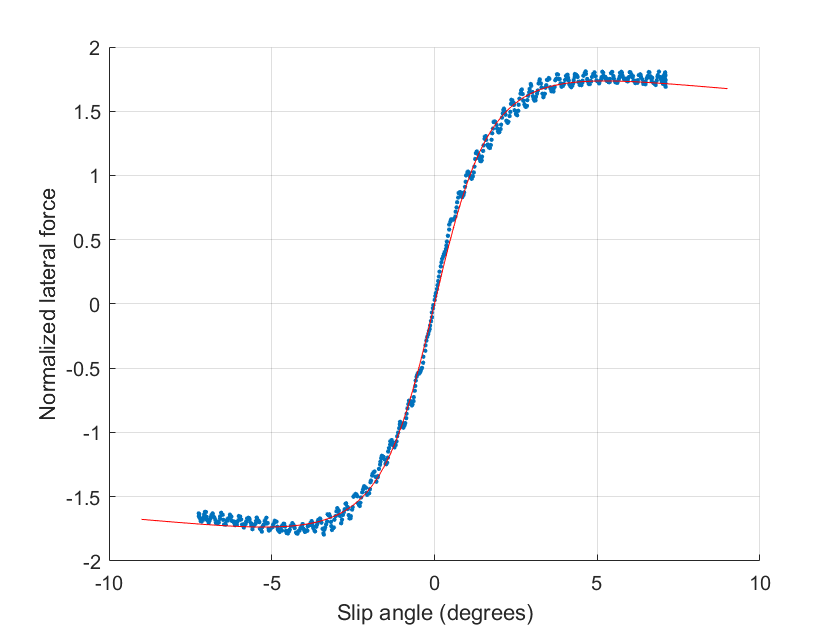


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.000000e+02.



C(8,:) = fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));


[SAlb,SAub]=groupdata(SA(loadlb(5):loadub(5)),3,0.19,loadub(4))

SAlb =         4997
        5309
        5931


SAub =         5308
        5930
        6245


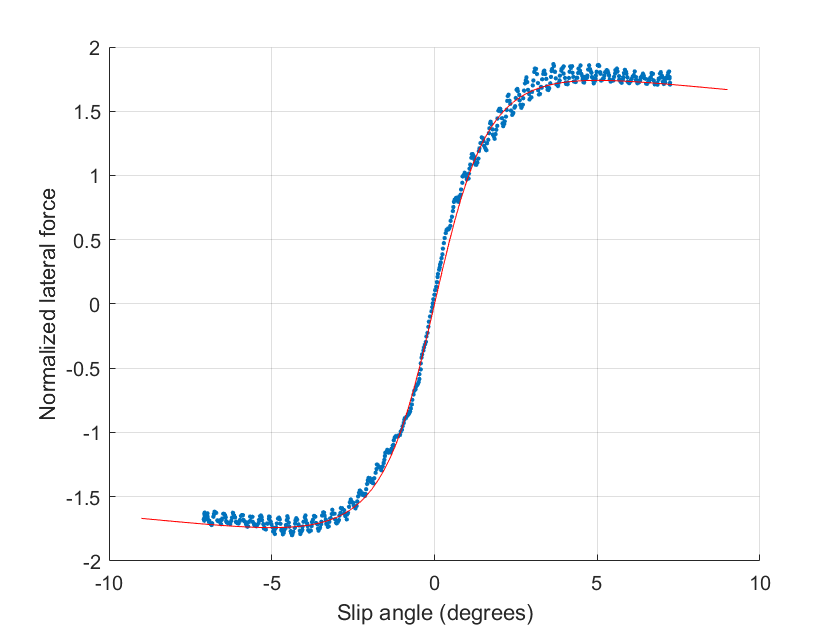


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.000000e+02.



C(9,:) = fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA

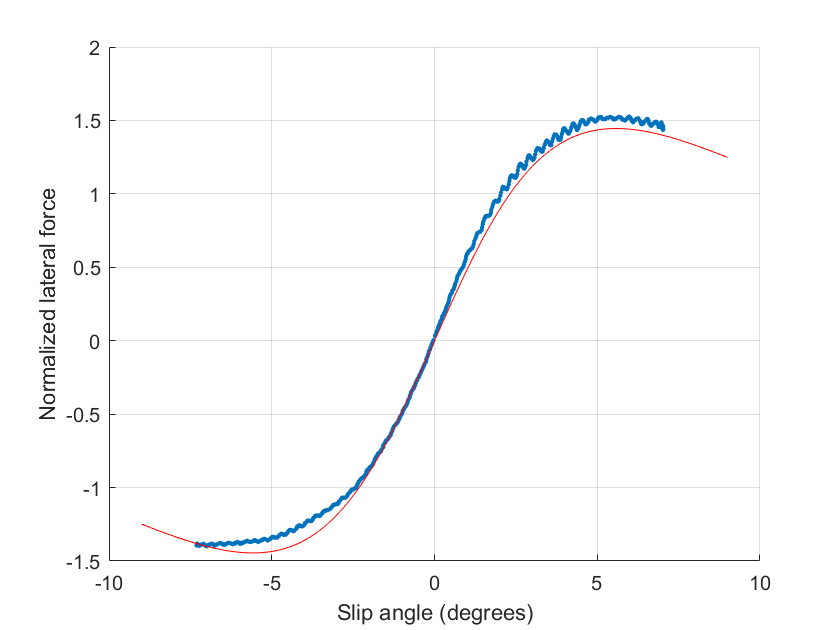


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.000000e+02.



C(10,:) = fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));


[SAlb,SAub]=groupdata(SA(loadlb(6):loadub(6)),3,0.19,loadub(5))

SAlb =         6246
        6559
        7181


SAub =         6558
        7180
        7495


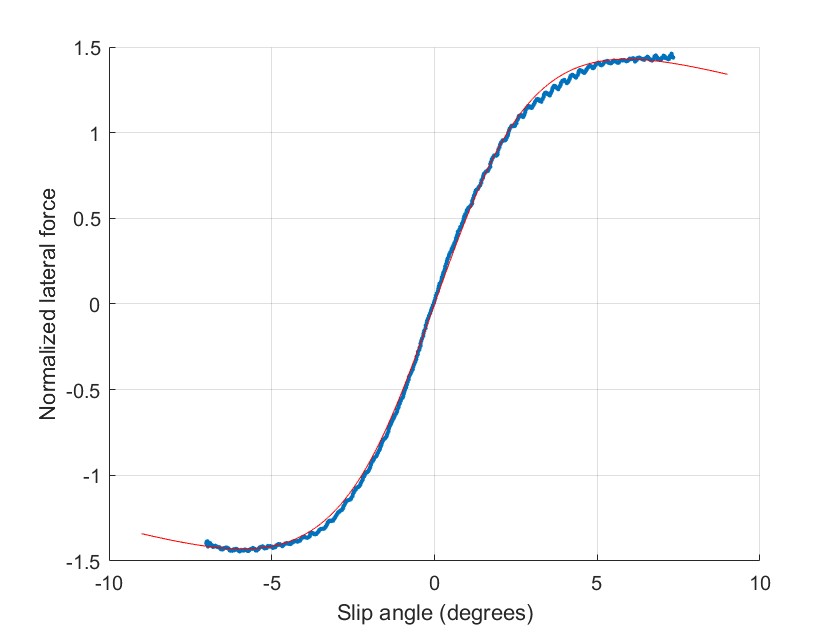


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.000000e+02.



C(11,:) = fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA

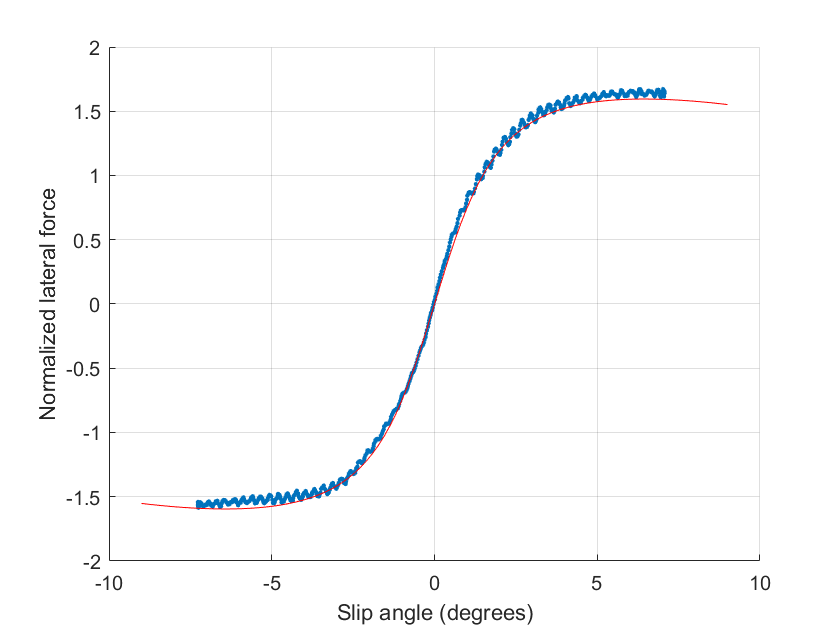


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


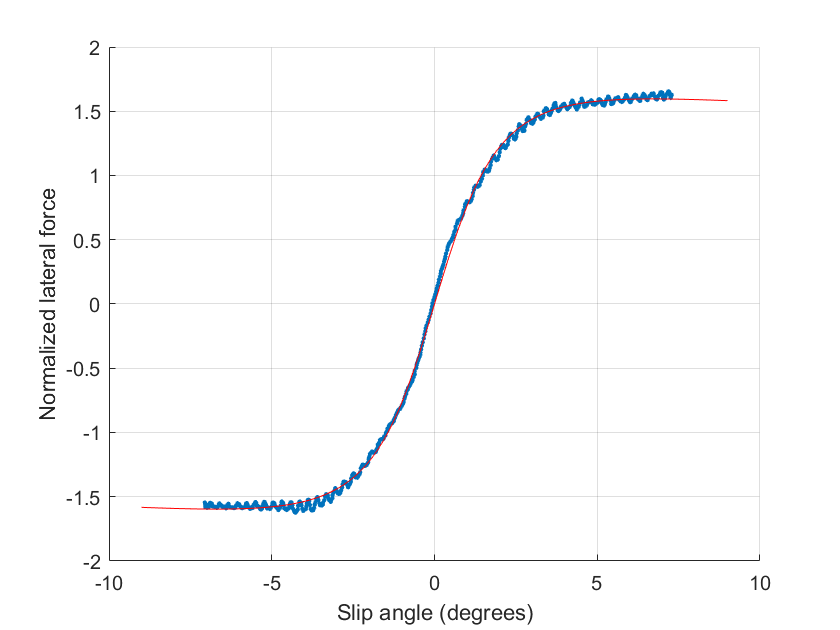

C(12,:) = fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));


save('pacejka_coefficients_lateral.mat',"C");

Define Pacejka function:

function y = pacejka(C,x)
tanx=tan(deg2rad(x));
y=C(3)*sin(C(2)*atan(C(1)*(1-C(4))*tanx+C(4)*atan(C(1)*tanx)));
end

Fit curve for a single vertical load group:

function C = fit(xdata,ydata)
hold off
scalefactor=0.6;
scatter(xdata*scalefactor,ydata*scalefactor,5,'filled')
hold on
lb=-inf*ones(4,1);
ub=inf*ones(4,1);
C0=[1,1,1,1];
[Cfinal,resnorm,~,exitflag,output] = lsqcurvefit(@(C,x) pacejka(C,x),C0,xdata,ydata);
x=linspace(-15,15);
plot(x*scalefactor,pacejka(Cfinal,x)*scalefactor,'red')
xlabel('Slip angle (degrees)')
ylabel('Normalized lateral force')
grid on
hold off
C=Cfinal;
end

Grouping data:

function [lb,ub] = groupdata(data,n,range,start)
    lb=zeros(n,1);
    ub=zeros(n,1);
    lb(1)=1;
    x = 0;
    for i=1:n
        if i>1
            lb(i)=ub(i-1)+1;
        end
        while 1
            x=x+1;
            if (x == size(data,1)) || (abs(data(x) - data(x+1)) > range)
                ub(i)=x;
                break
            end
        end
    end
    lb=lb+start*ones(n,1);
    ub=ub+start*ones(n,1);
end